%L2.b. Controllability, Observability and Pole placement

% Problem 1
% To check the controllability and observability of the control system

% State space matrices
A=[0 1 0;0 0 1;-6 -11 -6];
B=[0;0;1];
C=[4 5 1];
% Observability matrix
Ob=obsv(A,C);
% Order of system
no=size(A,1);
% Check observability
if rank(Ob)==no
    disp('System is observable')
else
    disp('System is not observable')
end

System is not observable



% Controllability matrix
CO=ctrb(A,B);

% Check controllability
if rank(CO)==no
    disp('System is controllable')
else
    disp('System is not controllable')
end

System is controllable


% Manual controllability matrix
CO1=[B A*B A^2*B];
% Rank of controllability matrix
rank(CO1)

ans = 3

% Manual observability matrix
OB1=[C;C*A;C*A^2];
% Rank of observability matrix
rank(OB1)

ans = 2

%L2.b. Controllability, Observability and Pole placement

% Problem 2
% Pole Placement by Ackermann's Formula

% State space matrices
A=[0 1 0;0 0 1;-6 -11 -6];
B=[0;0;1];
C=[4 5 1];
% Open loop poles
eig(A)

ans =    -1.0000
   -2.0000
   -3.0000


% Controllability matrix
CO=[B A*B A^2*B];
% Check controllability
nc=size(A,1);
if rank(CO)==nc
    disp('System is controllable and pole placement is possible')
else
    disp('System is not controllable and pole placement is not possible')
end

System is controllable and pole placement is possible


% Desired closed loop poles in matrix form
P=[-8.4563 0 0;
   0 -0.7718+0.5919i 0;
   0 0 -0.7718-0.5919i];
% Desired closed loop poles in vector form
P1=[-8.4563;
    -0.7718+0.5919i;
    -0.7718-0.5919i];
% Desired characteristic polynomial coefficients
poly(P)

ans =     1.0000    9.9999   13.9992    7.9998


% Desired characteristic polynomial matrix
Phi=polyvalm(poly(P),A);
% Ackermann formula
K0=[0 0 1]*inv(CO)*Phi

K0 =     1.9998    2.9992    3.9999


% Closed loop system matrix
Acl0=A-B*K0;
% Closed loop poles
eig(Acl0)

ans =   -8.4563 + 0.0000i
  -0.7718 + 0.5919i
  -0.7718 - 0.5919i


% Verification using acker
Kacker1=acker(A,B,P1);
Acl1=A-B*Kacker1;
eig(Acl1)

ans =   -8.4563 + 0.0000i
  -0.7718 + 0.5919i
  -0.7718 - 0.5919i


% Verification using place
Kacker2=place(A,B,P1);
Acl2=A-B*Kacker2;
eig(Acl2)

ans =   -8.4563 + 0.0000i
  -0.7718 + 0.5919i
  -0.7718 - 0.5919i


%L2.b. Controllability, Observability and Pole placement

% Exercise 1(a)
% Pole placement by controllable canonical form transformation method

% State space matrices
A=[0 1 0;0 0 1;-6 -11 -6];
B=[0;0;1];
C=[4 5 1];
% Open loop poles
eig(A)

ans =    -1.0000
   -2.0000
   -3.0000


% System order
no=size(A,1);
% Controllability matrix
CO=ctrb(A,B);
% Rank of controllability matrix
rank(CO)

ans = 3

% Check controllability
if rank(CO)==no
    disp('System is controllable and arbitrary pole placement can be done')
else
    disp('System is not controllable and arbitrary pole placement is not possible')
end

System is controllable and arbitrary pole placement can be done


% Open loop characteristic polynomial
ja=poly(A);
% Extraction of coefficients
a1=ja(2);
a2=ja(3);
a3=ja(4);
% Weighting matrix
w=[a2 a1 1;
   a1 1 0;
   1 0 0];
% Transformation matrix
t=CO*w;
% Desired closed loop pole locations
j=[-1+2i 0 0;
   0 -1-2i 0;
   0 0 -6];
% Desired characteristic polynomial
jj=poly(j);
% Extraction of desired coefficients
alpha1=jj(2);
alpha2=jj(3);
alpha3=jj(4);
% Feedback gain matrix
k=[alpha3-a3 alpha2-a2 alpha1-a1]*inv(t)

k =    24.0000    6.0000    2.0000


% Closed loop system matrix
Acl=A-B*k;
% Closed loop poles
eig(Acl)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -6.0000 + 0.0000i


%L2.b. Controllability, Observability and Pole placement

% Exercise 1(b)
% Pole placement by controllable canonical transformation method 2

% State space matrices
A=[0 1 0;0 0 1;-6 -11 -6];
B=[0;0;1];
C=[4 5 1];

% Open loop poles
eig(A)

ans =    -1.0000
   -2.0000
   -3.0000


% System order
no=size(A,1);
% Controllability matrix
CO=ctrb(A,B);
% Rank of controllability matrix
rank(CO)

ans = 3

% Check controllability
if rank(CO)==no
    disp('System is controllable and arbitrary pole placement can be done')
else
    disp('System is not controllable and arbitrary pole placement is not possible')
end

System is controllable and arbitrary pole placement can be done


% Open loop characteristic polynomial
ja=poly(A);
% Extraction of characteristic polynomial coefficients
a1=ja(2);
a2=ja(3);
a3=ja(4);
% Last row of inverse controllability matrix
p1=inv(CO);
p1=p1(3,:);
% Transformation matrix
V=[p1;
   p1*A;
   p1*A*A];
% Controllable canonical form transformation
AC=V*A*inv(V)

AC =     0.0000    1.0000    0.0000
         0    0.0000    1.0000
   -6.0000  -11.0000   -6.0000


BC=V*B

BC =     0.0000
   -0.0000
    1.0000


% Last row of controllable canonical form matrix
alpha=AC(3,:)

alpha =    -6.0000  -11.0000   -6.0000


% Desired closed loop poles
P=[-1+2i -1-2i -6];
% Desired characteristic polynomial
lambda=poly(P);
% Desired coefficients
lambda=lambda(2:4);
% State feedback gain matrix in CCF
K1=[alpha(1)+lambda(3) alpha(2)+lambda(2) alpha(3)+lambda(1)]

K1 =    24.0000    6.0000    2.0000


% State feedback gain matrix for original system
K=K1*V

K =    24.0000    6.0000    2.0000


% Closed loop poles
eig(A-B*K)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -6.0000 + 0.0000i


% Verification in controllable canonical form
eig(AC-BC*K1)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -6.0000 + 0.0000i


% Ackermann formula
Kacker=[0 0 1]*inv(CO)*(A*A*A+lambda(1)*A*A+lambda(2)*A+lambda(3)*eye(3))

Kacker =    24.0000    6.0000    2.0000


% Verification using acker command
Kacker1=acker(A,B,P)

Kacker1 =     24     6     2


%L2.b. Controllability, Observability and Pole placement

% Exercise 2
% Pole placement using place command
% Find the control gain F such that the closed loop poles are
% at [-1+2i -1-2i -6]
% Verify by finding the eigenvalues of A-BF

% State space matrices
A=[-1 0 0;
   1 -2 0;
   2 1 -3];
B=[10;
   1;
   0];
% Desired closed loop poles
P=[-1+2i -1-2i -6];
% Feedback gain matrix
F=place(A,B,P)

F =    -0.2222    4.2222   -2.0000


% Closed loop system matrix
Acl=A-B*F

Acl =     1.2222  -42.2222   20.0000
    1.2222   -6.2222    2.0000
    2.0000    1.0000   -3.0000


% Verification of closed loop poles
eig(Acl)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -6.0000 + 0.0000i


%L2.b. Controllability, Observability and Pole placement

% Exercise 3
% Obtain the state models in Jordan canonical form
% Plot the pole-zero map
% Determine controllability and observability
% Place the poles at -4, -8, -10

% State space matrices
A=[-2 -2.5 -0.5;
    1 0 0;
    0 1 0];
B=[1;
   0;
   0];
C=[1 4 3.5];
D=0;
% Jordan canonical form
[P,J]=jordan(A)

P =    0.0580 + 0.0000i  -0.5290 + 2.0079i  -0.5290 - 2.0079i
  -0.2408 + 0.0000i  -0.8796 - 1.1414i  -0.8796 + 1.1414i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


J =   -0.2408 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.8796 - 1.1414i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.8796 + 1.1414i


% Transformed state matrices
BJ=inv(P)*B

BJ =    0.5845 + 0.0000i
  -0.2923 - 0.1636i
  -0.2923 + 0.1636i


CJ=C*P

CJ =    2.5948 + 0.0000i  -0.5474 - 2.5575i  -0.5474 + 2.5575i


DJ=D

DJ = 0

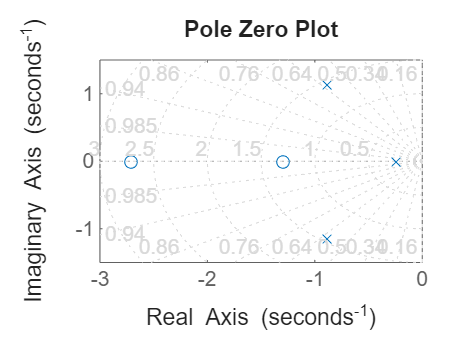

% Pole-zero plot
[num,den]=ss2tf(A,B,C,D);
G=tf(num,den);
figure(1)
pzmap(G)
grid on
title('Pole Zero Plot')

% Controllability matrix
CO=ctrb(A,B);
% Rank of controllability matrix
rank(CO)

ans = 3

% Check controllability
if rank(CO)==size(A,1)
    disp('System is controllable')
else
    disp('System is not controllable')
end

System is controllable


% Observability matrix
OB=obsv(A,C);
% Rank of observability matrix
rank(OB)

ans = 3

% Check observability
if rank(OB)==size(A,1)
    disp('System is observable')
else
    disp('System is not observable')
end

System is observable


% Desired closed loop poles
Pdes=[-4 -8 -10];
% State feedback gain using place command
K=place(A,B,Pdes)

K =    20.0000  149.5000  319.5000


% Closed loop system matrix
Acl=A-B*K;
% Verification of closed loop poles
eig(Acl)

ans =   -10.0000
   -8.0000
   -4.0000


%L2.b. Controllability, Observability and Pole placement

% Exercise 4
% Place the poles of the system
% A=[-0.1 5 0.1;-5 -0.1 5;0 0 -10]
% B=[0;0;10]
% at (i) -1+j5, -1-j5, -10
% (ii) -5, -60, -70
% Find and compare the norms of F

% State space matrices
A=[-0.1 5 0.1;
   -5 -0.1 5;
    0 0 -10];
B=[0;
   0;
   10];
% Desired poles - Case 1
P1=[-1+5i -1-5i -10];
% Feedback gain matrix
F1=place(A,B,P1)

F1 =    -0.1404    0.3754    0.1800


% Closed loop poles
eig(A-B*F1)

ans =   -1.0000 + 5.0000i
  -1.0000 - 5.0000i
 -10.0000 + 0.0000i


% Norm of F1
normF1=norm(F1)

normF1 = 0.4394

% Desired poles - Case 2
P2=[-5 -60 -70];
% Feedback gain matrix
F2=place(A,B,P2)

F2 =    70.4864   94.5509   12.4800


% Closed loop poles
eig(A-B*F2)

ans =    -5.0000
  -60.0000
  -70.0000


% Norm of F2
normF2=norm(F2)

normF2 = 118.5915

% Comparison of norms
disp('Norm of F for Case 1')

Norm of F for Case 1


disp(normF1)

    0.4394



disp('Norm of F for Case 2')

Norm of F for Case 2


disp(normF2)

  118.5915



%L2.b. Controllability, Observability and Pole placement

% Exercise 5
% A SISO system represented by
% A=[-1 0 0;0 -2 -2;-1 0 -3]
% Consider two cases
% B1=[1;1;1]
% B2=[1;1;0]
% i) Check controllability
% ii) Find eigenvalues
% iii) Find transformation matrix V that transforms the system
%      to controllable canonical form
% iv) Determine state feedback matrix K required to assign
%      eigenvalues at [-2 -4 -6]

% State matrix
A=[-1 0 0;
    0 -2 -2;
   -1 0 -3];
% Case 1
B1=[1;
    1;
    1];
% Eigenvalues
eig(A)

ans =     -2
    -3
    -1


% Controllability matrix
CO1=ctrb(A,B1);
% Rank of controllability matrix
rank(CO1)

ans = 3

% Check controllability
if rank(CO1)==size(A,1)
    disp('Case 1: System is controllable')
else
    disp('Case 1: System is not controllable')
end

Case 1: System is controllable


% Transformation matrix
p1=inv(CO1);
p1=p1(3,:);
V1=[p1;
    p1*A;
    p1*A*A]

V1 =          0    0.3333   -0.3333
    0.3333   -0.6667    0.3333
   -0.6667    1.3333    0.3333


% Desired poles
P=[-2 -4 -6];
% State feedback gain
K1=place(A,B1,P)

K1 =     7.0000         0   -1.0000


% Verification
eig(A-B1*K1)

ans =    -2.0000
   -6.0000
   -4.0000


% Case 2
B2=[1;
    1;
    0];
% Controllability matrix
CO2=ctrb(A,B2);
% Rank of controllability matrix
rank(CO2)

ans = 3

% Check controllability
if rank(CO2)==size(A,1)
    disp('Case 2: System is controllable')
else
    disp('Case 2: System is not controllable')
end

Case 2: System is controllable


% Transformation matrix
p2=inv(CO2);
p2=p2(3,:);
V2=[p2;
    p2*A;
    p2*A*A]

V2 =     -1     1    -1
     2    -2     1
    -3     4     1


% State feedback gain
K2=place(A,B2,P)

K2 =     6.0000         0   -3.0000


% Verification
eig(A-B2*K2)

ans =    -2.0000
   -6.0000
   -4.0000
